# Dynamics Simulation 

Dynamic Simulation for the 2 DoF Space Robot

clc
load 'SC_2DoF.mat'

sc.homeConfig();

Specify Forces

f0 = [0.5; 0; 0];     % Forces on base [fx, fy, fz], in base frame
n0 = [0; 0; 0];     % Torques on base [nx, ny, nz], in base frame
tau_qm = [0; 0];      % Joint torques

### Spart Init

filename='SC_2DoF.urdf';
[robotSpart,robot_keys] = urdf2robot(filename);

q00=[0;0;0;1;sc.q0(1:3)];
qm0=sc.qm;
u00=zeros(6,1);
um0=zeros(2,1);
u0dot0=zeros(6,1);
umdot0=zeros(2,1);

%Compute Initial momentum (M0) and initial matrices.
R0=quat_DCM([q00(1:4)]')';

%Kinematics
[RJ,RL,rJ,rL,e,g]=Kinematics(R0,q00(4:6),qm0,robotSpart);
%Differential Kinematics
[Bij,Bi0,P0,pm]=DiffKinematics(R0,q00(4:6),rL,e,g,robotSpart);

%Inertias
[I0,Im]=I_I(R0,RL,robotSpart);
%Mass Composite Body matrix
[M0_tilde,Mm_tilde]=MCB(I0,Im,Bij,Bi0,robotSpart);
%Generalized Inertia matrix
[H0, H0m, Hm] = GIM(M0_tilde,Mm_tilde,Bij,Bi0,P0,pm,robotSpart);
M0 = H0*u00+H0m*um0;

### Launch Simulation

% profile on
tic
simRes = sim('sim_test');

obj =   SpaceRobot with properties:

                  Name: 'spaceRobot'
              NumLinks: 3
       NumActiveJoints: 2
                 Links: {[1×1 Link]  [1×1 Link]  [1×1 Link]}
             LinkNames: {'Link1'  'Link2'  'endeffector'}
                  Base: [1×1 SpacecraftBase]
              BaseName: 'spacecraftBase'
                     q: [8×1 double]
                    q0: [6×1 double]
                    qm: [2×1 double]
                 q_dot: [8×1 double]
                q0_dot: [6×1 double]
                qm_dot: [2×1 double]
                 Ttree: [1×1 struct]
            Ttree_symb: [1×1 struct]
    CoMJacobsBase_symb: [1×1 struct]
           Jacobs_symb: []
                Config: [1×1 struct]
                q_symb: [8×1 sym]
            q_dot_symb: [8×1 sym]
                H_symb: [8×8 sym]
                C_symb: [8×8 sym]
                Q_symb: [8×8 sym]
                     H: [8×8 double

toc

Elapsed time is 1.601102 seconds.


% profile viewer
% profile off

### Animate Results

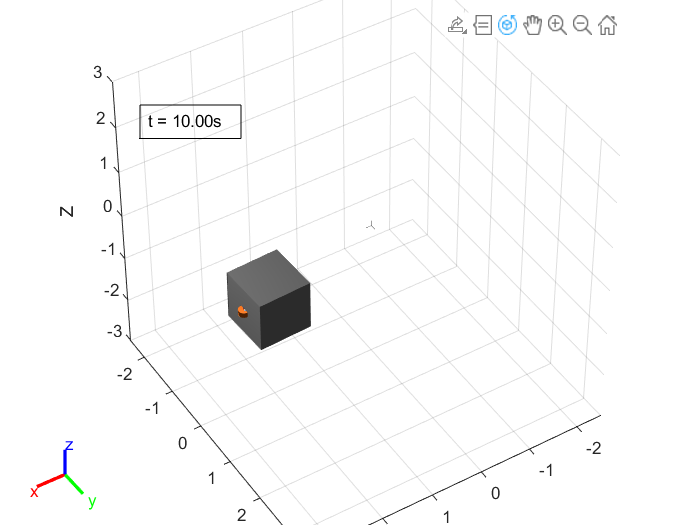

close all
dim = [.2 .5 .3 .3];

framesPerSecond = length(simRes.tout)/simRes.tout(end);
r = rateControl(framesPerSecond);
str = sprintf('t = %.2fs', 0);
h_annot = annotation('textbox', dim,'String', str,'FitBoxToText','on');

for i = 1:length(simRes.q.Time)
    sc.q = simRes.q.Data(:, :, i);
    sc.show('preserve', false, 'fast', true, 'visuals', 'on');
    curT = i/framesPerSecond;
    str = sprintf('t = %.2fs', curT);    
    h_annot.set('String',str);
    drawnow
    waitfor(r);
end

r.DesiredPeriod

ans = 0.1852

r.statistics.AveragePeriod

ans = 0.2054